# ESA Signals Acoustic Modem Project

#### Elvis Wolcott and Melissa Kazazic

Deliverables:

1. A brief report that includes an introduction, block diagram, equations used, graphs of signals in the time domain, and graphs of signals in the frequency domain.

2. Link to audio recordings if you produced new ones.

3. Your code.

4. Short demo video (2 minutes or less)

Start with hello example.

clear
load('short_modem_rx.mat');
symbol_period = 100;

Play and plot initial graphs of signal

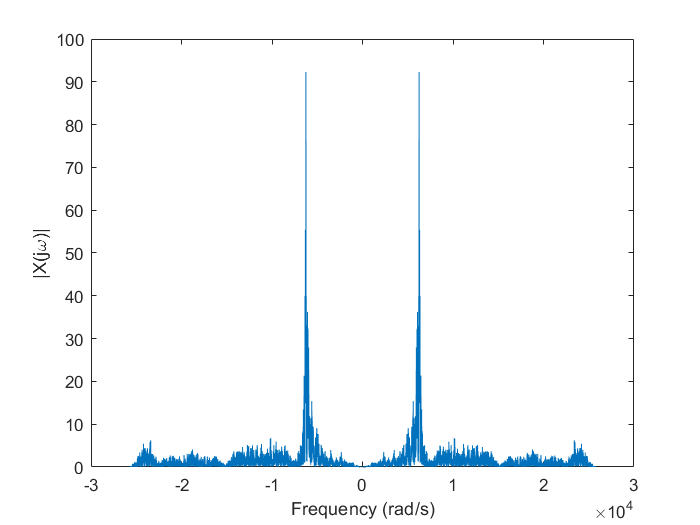

soundsc(y_r,Fs)
plot_ft_rad(y_r,Fs);

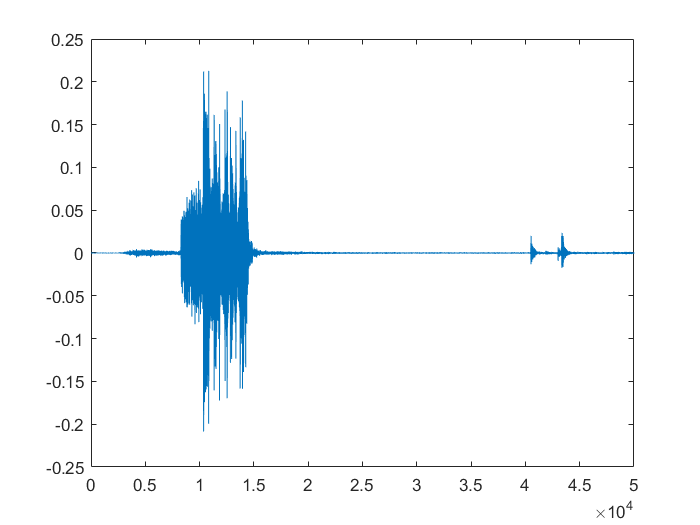

figure()
plot(y_r)

Find the start of the signal

index = find_start_of_signal(y_r,x_sync)

index = 8293

Trim according to start of signal

y_r_crop = y_r(index+length(x_sync):end);

Play and plot cropped signal

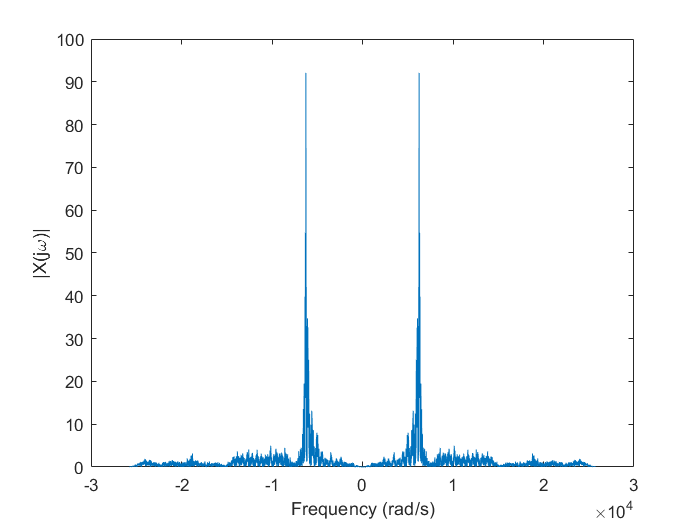

soundsc(y_r_crop,Fs)
plot_ft_rad(y_r_crop,Fs);

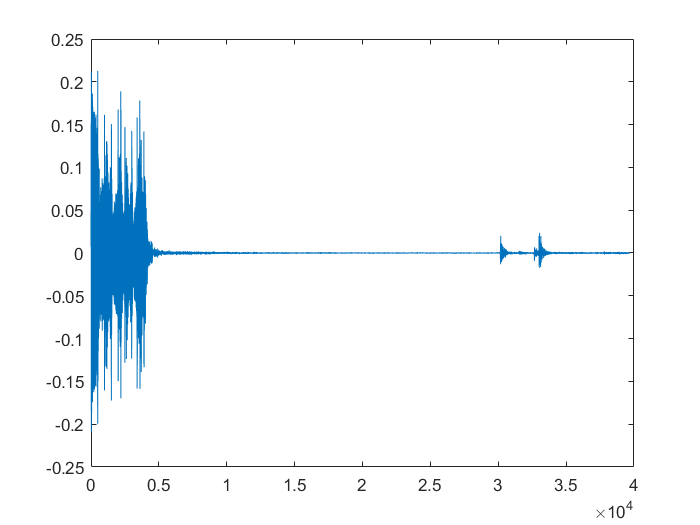

figure()
plot(y_r_crop)

Frequency Shift

t = (0:length(y_r_crop)-1)';
cos_fc = cos(2*pi*f_c/Fs*t);
y_shifted = y_r_crop.*cos_fc

y_shifted =     0.0076
   -0.0135
   -0.0020
   -0.0068
   -0.0336
   -0.0710
   -0.0040
   -0.0160
   -0.1139
   -0.1090


Play and plot shifted signal

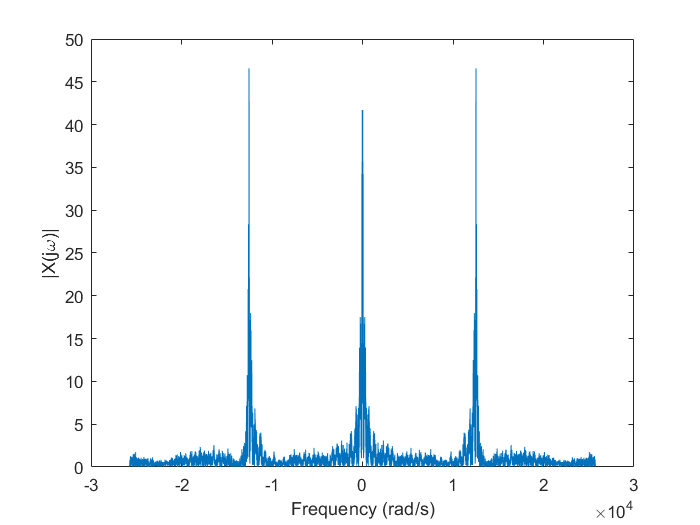

soundsc(y_shifted,Fs)
plot_ft_rad(y_shifted,Fs);

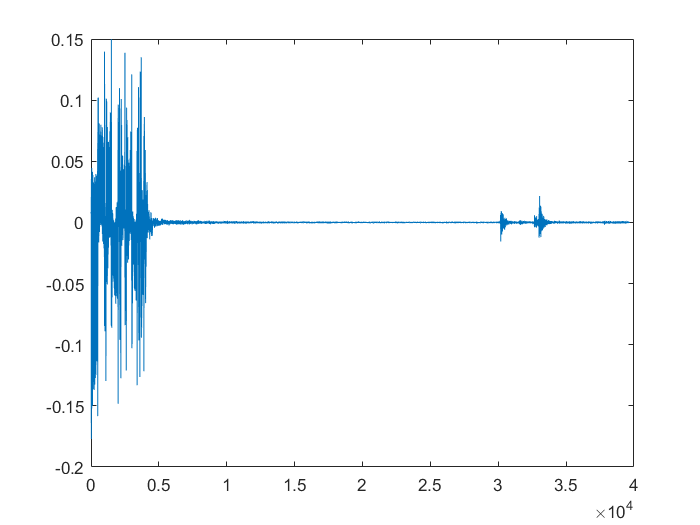

figure()
plot(y_shifted)

Filter shifted signal

y_filtered = lowpass(y_shifted, 1/2);

Play and plot filtered signal

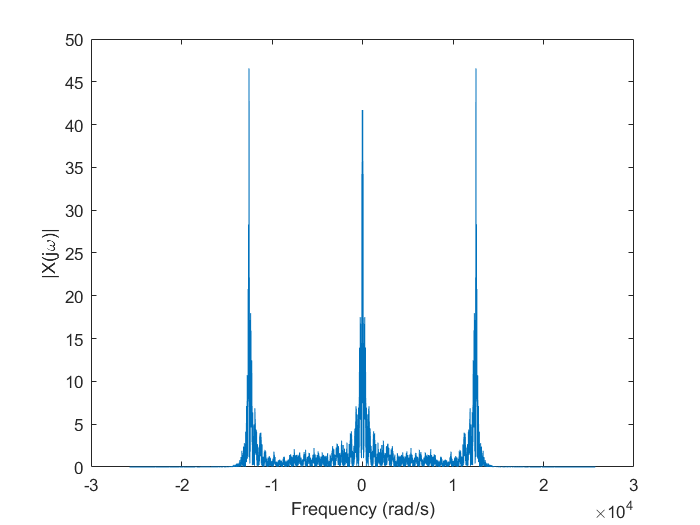

soundsc(y_filtered,Fs)
plot_ft_rad(y_filtered,Fs);

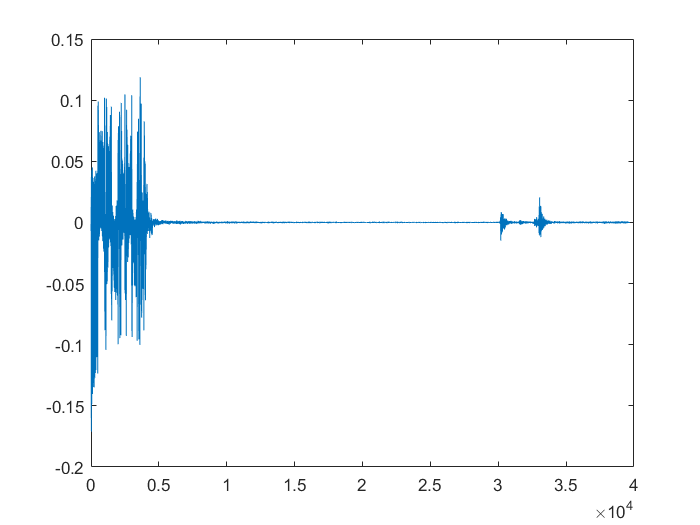

figure()
plot(y_filtered)